# Hughe's flow Third Attempt

## Defining the Domain

Nx = 200; Ny = 200; 
Lx = 1; Ly = 1; 
dx = Lx/Nx; dy = Ly/Ny; 
[x, y] = meshgrid(linspace(dx,Lx,Nx), linspace(dy,Ly,Ny));

## Setting the Parameters

Vmax = 2;
rho_max = 1;
CFL = 0.4;

obstacle = false(Ny, Nx);
obstacle(1:100,100:120) = true;

## Initialising the Initial Condition

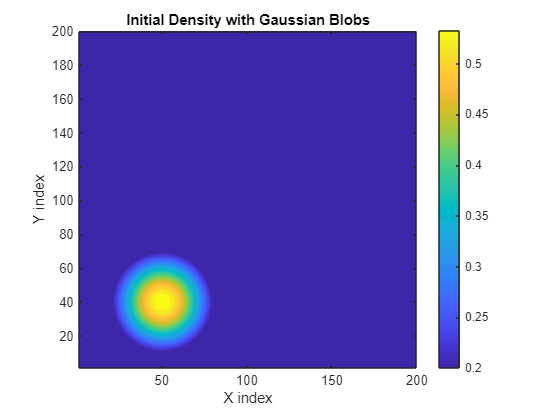

% Domain setup
rho = 0.2 * ones(Nx, Ny);

% === Blob 1 parameters ===
a1 = 0.55;  b1 = 0.2;  D1 = 60;  
xc1 = 50;  yc1 = 40;
% Compute widths
R1 = D1 / 2;  sigma1 = R1 / sqrt(2 * log(a1 / b1));

% Create grid
[x, y] = meshgrid(1:Ny, 1:Nx);

% Gaussian blobs
G1 = a1 * exp(-((x - xc1).^2 + (y - yc1).^2) / (2 * sigma1^2));

% === Combine blobs and background ===
rho = max(rho, G1);
rho = min(rho, rho_max);

% === Plot ===
figure;
contourf(rho, 20, 'LineColor', 'none');
colorbar;
axis equal tight;
xlabel('X index');
ylabel('Y index');
title('Initial Density with Gaussian Blobs');

## The main function for time marching

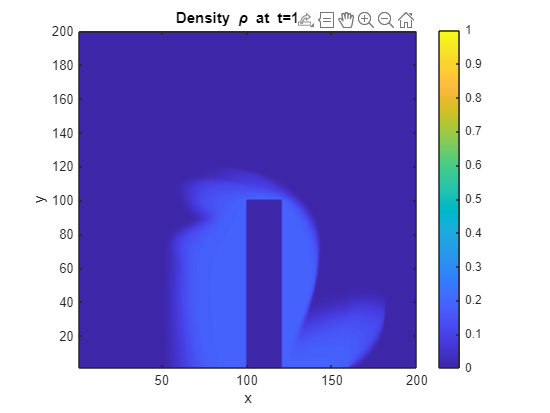

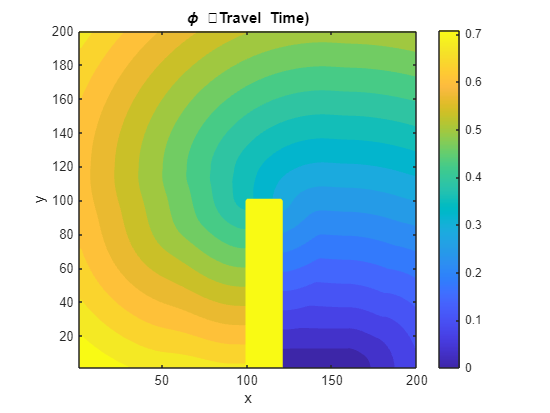

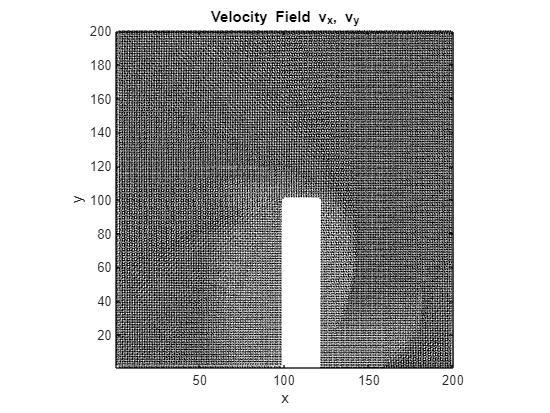

Tfinal = 1.5; 
t = 0; 
while t < Tfinal 
    % Speed field 
    f = Vmax*(1 - rho/rho_max); 
    % To speed doesn't become zero completely 
    f(f<1e-6) = 1e-6; 
    % Solve eikonal equation 
    phi = fast_sweeping(1./f,dy,dx,Nx,Ny,obstacle); 
    % Direction field 
    [phix, phiy] = gradient(phi, dx, dy); 
    grad_mag = sqrt(phix.^2 + phiy.^2) + 1e-12; 
    dirx = -phix ./ grad_mag; 
    diry = -phiy ./ grad_mag; 
    % Velocity field 
    vx = f .* dirx;
    vy = f .* diry; 
    % Time step 
    maxspeed = max(max(sqrt(vx.^2 + vy.^2))); 
    dt = CFL * min(dx,dy) / maxspeed; 
    if t+dt > Tfinal, dt = Tfinal-t; end 
    % Update rho 
    rho = upwind_update(rho, vx, vy, dx, dy, dt,rho_max,obstacle);
    % Advance time 
    t = t + dt;
    % Plots 
    if mod(round(t/dt),2) == 0 
        % Density (phi) 
        figure(1); 
        contourf(x, y, rho, 20, 'LineColor', 'none'); 
        colorbar; 
        caxis([0 rho_max]); 
        title(sprintf('Density \\rho at t=%.2f', t)); 
        xlabel('x'); ylabel('y'); 
        axis equal tight; 
        % Potential (phi) 
        figure(2);
        contourf(x, y, phi, 20, 'LineColor', 'none'); 
        colorbar; title('\phi Travel Time)'); 
        xlabel('x'); ylabel('y'); 
        axis equal tight; 
        % Velocity field 
        figure(3); 
        quiver(x, y, vx, vy, 0.5, 'k'); 
        title('Velocity Field \bf{v_x, v_y}'); 
        xlabel('x'); ylabel('y'); 
        axis equal tight;
        drawnow;
    end 
end

## Fast sweep Algorithm

function phi = fast_sweeping(invf, dy, dx, Nx, Ny,obstacle)

    %---------------------------------------------
    % Initialization
    %---------------------------------------------
    phi = inf(Ny, Nx);        % Initial potential field
    phi(1,121:160) = 0;

    % Set phi inside obstacle to Inf
    phi(obstacle) = inf;

    %---------------------------------------------
    % Fast Sweeping Iterations
    %---------------------------------------------
    for sweep = 1:20
        % === Sweep 1: i→, j→
        for i = 2:Nx-1
            for j = 2:Ny-1
                if ~obstacle(j, i)
                    phi = update_phi(phi, invf, i, j, dx);
                end
            end
        end

        % === Sweep 2: i←, j→
        for i = Nx-1:-1:2
            for j = 2:Ny-1
                if ~obstacle(j, i)
                    phi = update_phi(phi, invf, i, j, dx);
                end
            end
        end

        % === Sweep 3: i←, j←
        for i = Nx-1:-1:2
            for j = Ny-1:-1:2
                if ~obstacle(j, i)
                    phi = update_phi(phi, invf, i, j, dx);
                end
            end
        end

        % === Sweep 4: i→, j←
        for i = 2:Nx-1
            for j = Ny-1:-1:2
                if ~obstacle(j, i)
                    phi = update_phi(phi, invf, i, j, dx);
                end
            end
        end

        % Apply Neumann boundary conditions (copy from neighbors)
        phi(:, 1)   = phi(:, 2);       % Left
        phi(:, Nx)  = phi(:,Nx-1);               % Right (target)
        phi(1,1:120)   = phi(2,1:120);       % Top
        phi(1,121:160) = 0;
        phi(1,161:200)  = phi(2,161:200);
        phi(Ny, :)  = phi(Ny-1, :);    % Bottom

        % Ensure obstacle remains inf (in case any updates slipped through)
        phi(obstacle) = inf;
    end
end

% =========================================================
% Subfunction: Update one grid point using Godunov scheme
% =========================================================
function phi = update_phi(phi, invf, i, j, dx)
    a = min(phi(j, i-1), phi(j, i+1));   % x-direction neighbors
    b = min(phi(j-1, i), phi(j+1, i));   % y-direction neighbors
    f = invf(j, i);                      % Local inverse speed

    if abs(a - b) >= f * dx
        phi(j, i) = min(a, b) + f * dx;
    else
        inside = 2 * (f * dx)^2 - (a - b)^2;
        if inside >= 0
            phi(j, i) = (a + b + sqrt(inside)) / 2;
        end
    end
end


## Up-winding scheme

function rho_new = upwind_update(rho, vx, vy, dx, dy, dt, rho_max,obstacle)
    [Ny, Nx] = size(rho);
    
    % ---------------------------------------------
    % Boundary Conditions (Neumann/Dirichlet mix)
    % ---------------------------------------------
    for j = 2:Ny-1
        rho(j,1) = 0;                     % Inflow wall (Dirichlet)
        rho(j,Nx) = 0;         % Outflow wall (Neumann)
    end
    for i = 2:Nx-1
        rho(Ny,i) = 0;                    % Top wall
        if i>=121 || i<=160
            rho(1,i) = rho(2,i);
        else rho(1,i) = 0;
        end

    end
    
    rho(obstacle) = 0;                    % No density in obstacle

    % ---------------------------------------------
    % Initialize flux arrays
    % ---------------------------------------------
    flux_xp = zeros(Ny, Nx);
    flux_xm = zeros(Ny, Nx);
    flux_yp = zeros(Ny, Nx);
    flux_ym = zeros(Ny, Nx);

    % ---------------------------------------------
    % Upwind Scheme (Skip obstacle points)
    % ---------------------------------------------
    for j = 2:Ny-1
        for i = 2:Nx-1
            if ~obstacle(j, i)
                % x-direction fluxes
                flux_xp(j,i) = max(vx(j,i),0)*rho(j,i)   + min(vx(j,i),0)*rho(j,i+1);
                flux_xm(j,i) = max(vx(j,i),0)*rho(j,i-1) + min(vx(j,i),0)*rho(j,i);

                % y-direction fluxes
                flux_yp(j,i) = max(vy(j,i),0)*rho(j,i)   + min(vy(j,i),0)*rho(j+1,i);
                flux_ym(j,i) = max(vy(j,i),0)*rho(j-1,i) + min(vy(j,i),0)*rho(j,i);
            end
        end
    end

    % ---------------------------------------------
    % Update density using continuity equation
    % ---------------------------------------------
    rho_new = rho - (dt/dx)*(flux_xp - flux_xm) - (dt/dy)*(flux_yp - flux_ym);

    % ---------------------------------------------
    % Enforce bounds and obstacle exclusion
    % ---------------------------------------------
    rho_new = max(0, min(rho_max, rho_new));  % Clamp between 0 and max
end
